## **Forward Kinematics**

**Dependencies:**

- **Peter Corke's Robotics, Vision & Control toolbox**

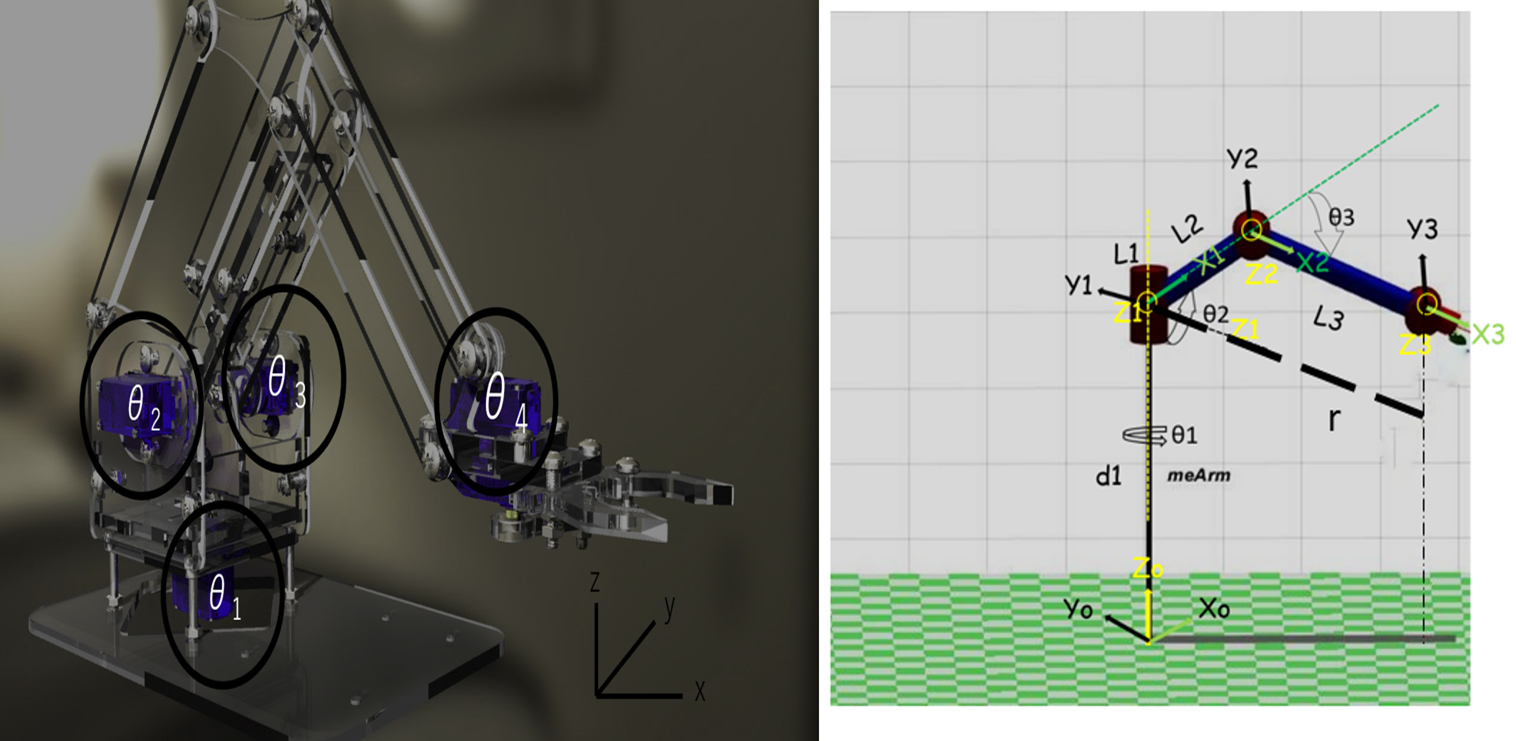

The forward kinematics equations are responsible for computing the position and orientation of the end effector given a set of joint angles. The forward kinematics were performed in accordance with the [Denavit—Hartenberg (D-H) convention](https://en.m.wikipedia.org/wiki/Denavit%E2%80%93Hartenberg_parameters). According to the D-H convention, any robot can be described kinematically by giving the values of four quantities, typically known as the D-H parameters, for each link. The link length *a* and the link twist *α *quantities*,*describe the link itself and the remaining two; link offset *d* and the joint angle *θ* describe the link’s connection to a neighboring link.

 The D-H parameters for the meArm were obtained as:

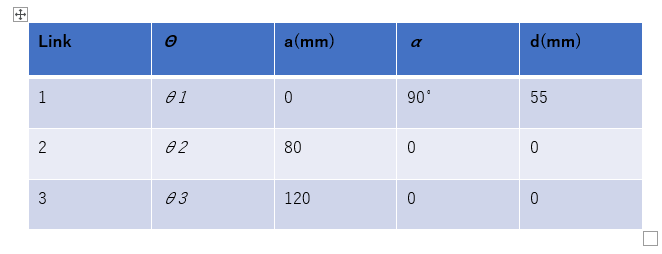

In this convention, each homogeneous transformation A*i* is represented as a product of four basic transformations, which evaluates to a 4by4 matrix that is used to transform a point from frame n to n-1.

A*i* = Rot*z,θi *Trans*z,di *Transx,ai Rot*x,αi*

The individual homogeneous transformations for the 3 links together with the total homogeneous transformation for the meArm were obtained as follows:

% firing up robotics toolbox
startup_rvc;

Robotics, Vision & Control: (c) Peter Corke 1992-2019 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.4)


 - ARTE contributed code: 3D models for robot manipulators (C:\Users\ADMIN\AppData\Roaming\MathWorks\MATLAB Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\robot\data\meshes)
 - pHRIWARE (release 1.2): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2021) (c)



syms th d alph a;

% homogeneous transformation matrix
A=trotz(th)*transl(0,0,d)*transl(a,0,0)*trotx(alph)

$$A = \left(\begin{array}{cccc} \cos\left(\mathrm{th}\right) & -\cos\left(\mathrm{alph}\right)\,\sin\left(\mathrm{th}\right) & \sin\left(\mathrm{alph}\right)\,\sin\left(\mathrm{th}\right) & a\,\cos\left(\mathrm{th}\right)\\ \sin\left(\mathrm{th}\right) & \cos\left(\mathrm{alph}\right)\,\cos\left(\mathrm{th}\right) & -\sin\left(\mathrm{alph}\right)\,\cos\left(\mathrm{th}\right) & a\,\sin\left(\mathrm{th}\right)\\ 0 & \sin\left(\mathrm{alph}\right) & \cos\left(\mathrm{alph}\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% link dimensions
d1 = -5.5; %offset
l1 = 0;
l2 = 8.0;
l3 = 12.0;

% homogeneous transformations for each link

%Link1
syms th1
A1=subs(A,{a,alph,d,th},{l1,pi/2,d1,th1})

$$A1 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & 0 & \sin\left({\mathrm{th}}_{1}\right) & 0\\ \sin\left({\mathrm{th}}_{1}\right) & 0 & -\cos\left({\mathrm{th}}_{1}\right) & 0\\ 0 & 1 & 0 & -\frac{11}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Link2
syms th2
A2=subs(A,{a,alph,d,th},{l2,0,0,th2})

$$A2 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\right) & -\sin\left({\mathrm{th}}_{2}\right) & 0 & 8\,\cos\left({\mathrm{th}}_{2}\right)\\ \sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right) & 0 & 8\,\sin\left({\mathrm{th}}_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Link3
syms th3
A3=subs(A,{a,alph,d,th},{l3,0,0,th3})

$$A3 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\right) & -\sin\left({\mathrm{th}}_{3}\right) & 0 & 12\,\cos\left({\mathrm{th}}_{3}\right)\\ \sin\left({\mathrm{th}}_{3}\right) & \cos\left({\mathrm{th}}_{3}\right) & 0 & 12\,\sin\left({\mathrm{th}}_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Considering the three links of the MeArm, the total homogeneous transformation will be a product of the transformations of the three links given as:

A*T =* A*1 *x A*2* x A*3*

At=simplify(A1*A2*A3)

$$At = \begin{array}{l} \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)\,\cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)\,\cos\left({\mathrm{th}}_{1}\right) & \sin\left({\mathrm{th}}_{1}\right) & 4\,\cos\left({\mathrm{th}}_{1}\right)\,\sigma_{1}\\ \cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)\,\sin\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)\,\sin\left({\mathrm{th}}_{1}\right) & -\cos\left({\mathrm{th}}_{1}\right) & 4\,\sin\left({\mathrm{th}}_{1}\right)\,\sigma_{1}\\ \sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right) & \cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right) & 0 & 12\,\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+8\,\sin\left({\mathrm{th}}_{2}\right)-\frac{11}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,\cos\left({\mathrm{th}}_{2}\right) \end{array}$$

The position and orientation of the end effector x, y, z of the meArm was consequently obtained from the total homogeneous transformation At, using the upper right 3x1 matrix as:

fk = At(:,4)

$$fk = \left(\begin{array}{c} 4\,\cos\left({\mathrm{th}}_{1}\right)\,\left(3\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,\cos\left({\mathrm{th}}_{2}\right)\right)\\ 4\,\sin\left({\mathrm{th}}_{1}\right)\,\left(3\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,\cos\left({\mathrm{th}}_{2}\right)\right)\\ 12\,\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+8\,\sin\left({\mathrm{th}}_{2}\right)-\frac{11}{2}\\ 1 \end{array}\right)$$

x = fk(1,1)

$$x = 4\,\cos\left({\mathrm{th}}_{1}\right)\,\left(3\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,\cos\left({\mathrm{th}}_{2}\right)\right)$$

y = fk(2,1)

$$y = 4\,\sin\left({\mathrm{th}}_{1}\right)\,\left(3\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,\cos\left({\mathrm{th}}_{2}\right)\right)$$

z = fk(3,1)

$$z = 12\,\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+8\,\sin\left({\mathrm{th}}_{2}\right)-\frac{11}{2}$$